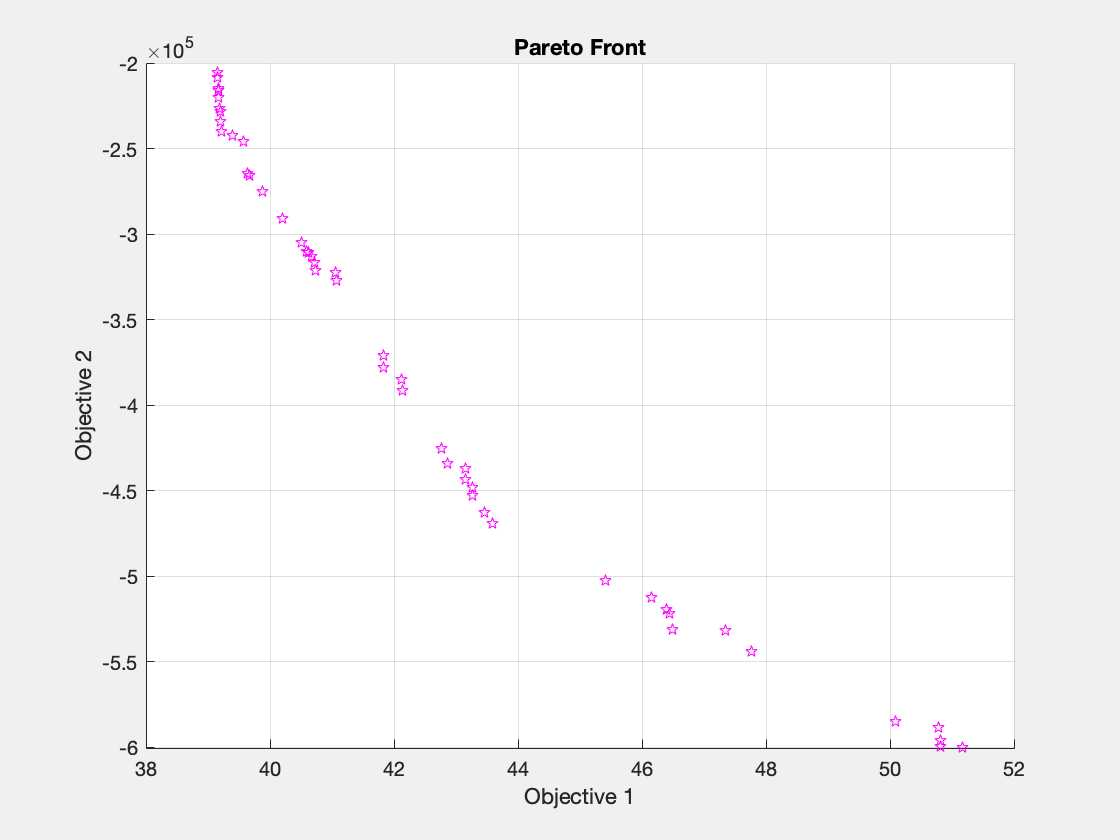

%% Set up script
clear all
clc
format long
%% Define the parameters
global D Q1 Q2 Kc K1 K2 T_inf h L1 L2 R1 R2 h_cell C_0_anode F rho_n rho_s rho_p rho_e rho_ccn rho_ccp x_ccn x_ccp  r_cell epsilon_s
%Thermal parameters
D = 20e-3; %Diameter of the cell in millimeter
Q1 = 8; %Heat generation in cathod W/m^3
Q2 = 10; %Heat generation in anode W/m^3
Kc = 20; %Seperator layer thermal conductivity
K1 = 10; %Cathode thermal conductivity
K2 = 5; %Anode thermal conductivity
L1 = 5.1e-8; %Cathode mean free path at 0% porosity
L2 = 3e-8; %Anode mean free path at 0% porosity
R1 = 1e-8; %Cathode particle size
R2 = 2e-9; %Anode particle size
T_inf = 30; %Coolant temperature in C
h = 0.009; %Coolant convection coeffiecent

%Energy density parameters
h_cell = 0.07; % height of cell in m
C_0_anode = 22055; %Concentraion of anode in mol/m^3
F = 96487; %Faraday's Constant in C/mol
rho_n = 2270; %Density of anode in kg/m^3
rho_s = 900; %Density of separator in kg/m^3
rho_p = 4140; %Density of cathode in kg/m^3
rho_e = 1210; %Density of electrolyte in kg/m^3
rho_ccn = 8700; % Density of negative current collector Cu foil kg/m^3
rho_ccp = 2700; % Density of positive current collector Al in foil kg/m^2
x_ccn = 0; % Thickness of negative current collector Cu foil in m (ASSUMED ZERO FOR SIMPLICITY)
x_ccp = 0; % Thick of positive current collector Al foil in m (ASSUMED ZERO FOR SIMPLICITY)
r_cell = 0.02; %m
epsilon_s = 0.46; %Porosity of Separator
%% Optimize

%Thermal
%Energy


fun = @objval;
nlcon = @nonlcon;
lb = [40e-6, 40e-6, 0.2, 0.2, 10e-6]; %Lower bound correct 
ub = [250e-6, 250e-6, 0.6, 0.6, 100e-6]; %Upper bound correct 
opts_ps = optimoptions('paretosearch','Display','off','PlotFcn','psplotparetof');
rng default % For reproducibility
npts = 60; % The default is 60
opts_ps.ParetoSetSize = npts;
[x_ps2,fval_ps2,~,psoutput2] = paretosearch(fun,5,[],[],[],[],lb,ub,nlcon,opts_ps);

disp("Total Function Count: " + psoutput2.funccount);

Total Function Count: 2761


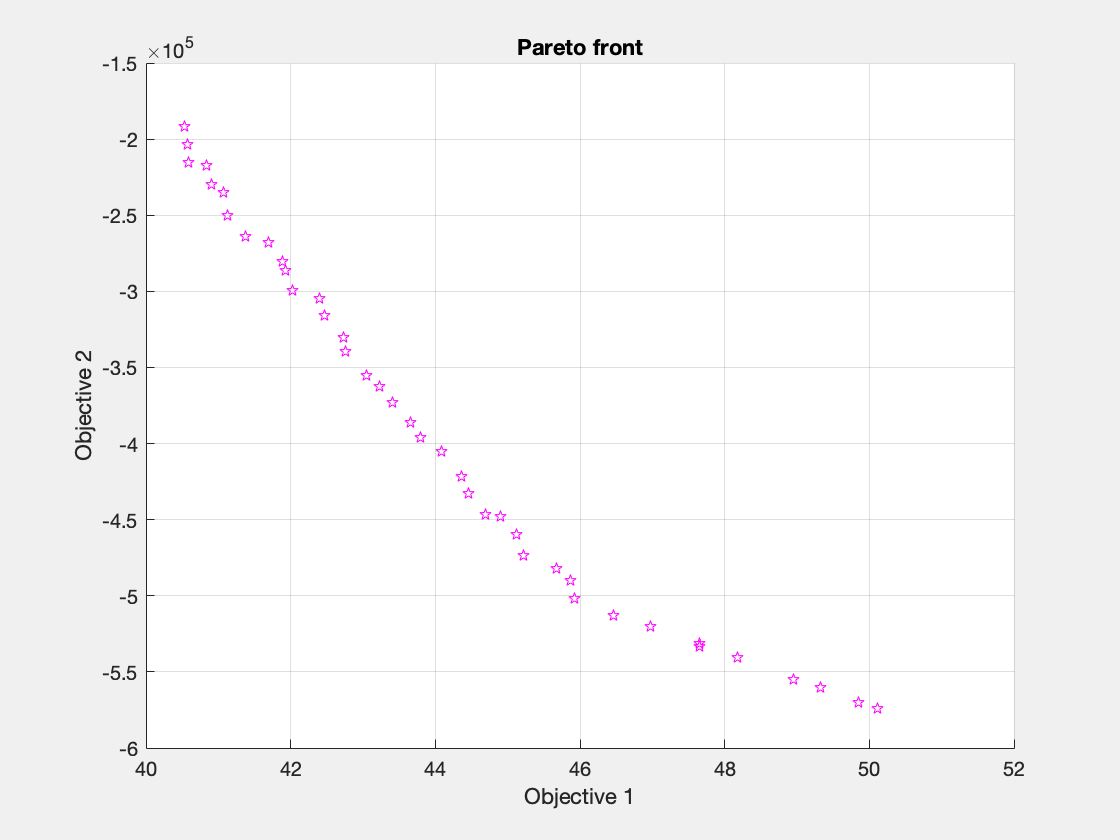

opts_ga = optimoptions('gamultiobj','Display','off','PlotFcn','gaplotpareto','PopulationSize',2*npts);
[x_ga1,fval_ga1,~,gaoutput1] = gamultiobj(fun,5,[],[],[],[],lb,ub,nlcon,opts_ga);

disp("Total Function Count: " + gaoutput1.funccount);

Total Function Count: 22801


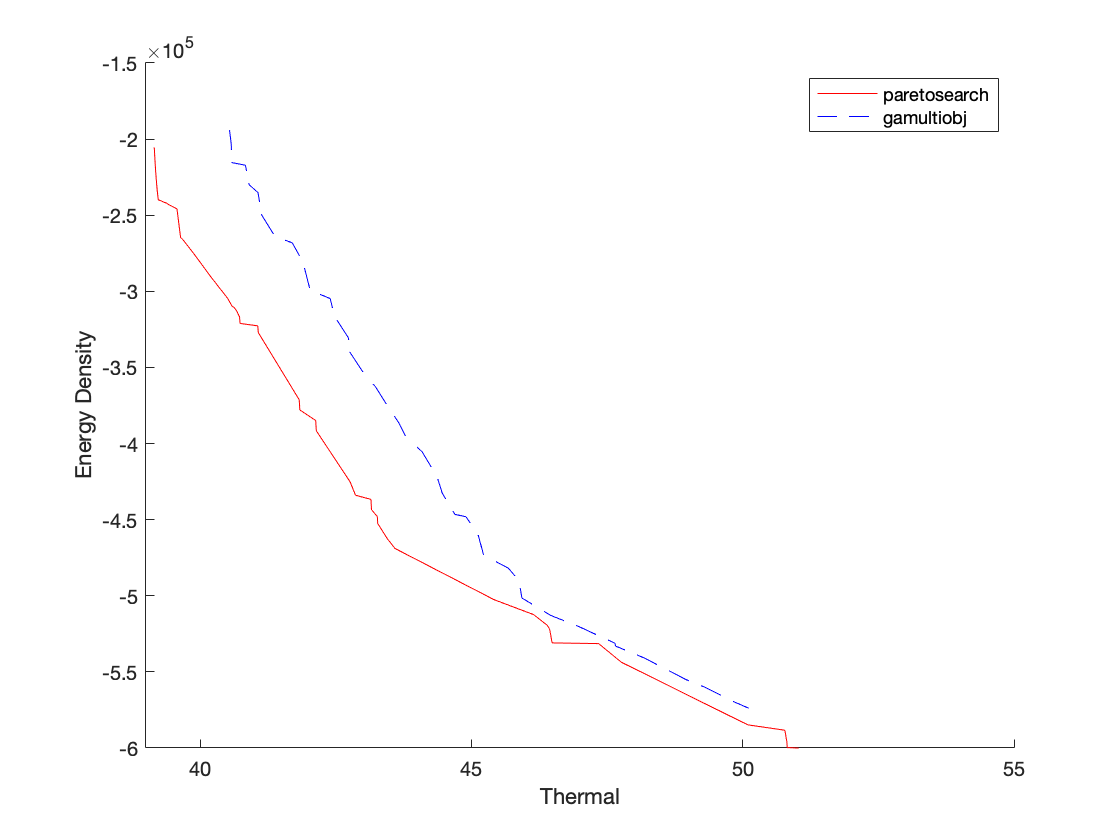

fps2 = sortrows(fval_ps2,1,'ascend');
figure
hold on
plot(fps2(:,1),fps2(:,2),'r-')
fga = sortrows(fval_ga1,1,'ascend');
plot(fga(:,1),fga(:,2),'b--')
xlim([39,55])
ylim([-6e5,-1.5e5])
legend('paretosearch','gamultiobj')
xlabel 'Thermal'
ylabel 'Energy Density'
hold off

whichgood = find(fval_ps2(:,1) <= 45 & fval_ps2(:,2) <= -4.5e5);
goodpoints = table(x_ps2(whichgood,:),fval_ps2(whichgood,:),'VariableNames',{'Parameters' 'Objectives'})

goodpoints = 3×2 table
                                                 Parameters                                                               Objectives              
    _____________________________________________________________________________________________________    _____________________________________

    4e-05    0.000128782088361195                     0.6                     0.2                  0.0001    43.5891895638403    -468903.618162604
    4e-05    0.000125010146932107       0.599966222808773           0.20013921875                  0.0001    43.4545517463199    -462824.466939443
    4e-05              0.00011875                     0.6                     0.2                  0.0001     43.270445571784    -452458.193800568


function Op = objval(x)
    global D Q1 Q2 Kc K1 K2 T_inf h L1 L2 R1 R2 h_cell C_0_anode F rho_n rho_s rho_p rho_e rho_ccn rho_ccp x_ccn x_ccp  r_cell epsilon_s
    x1 = x(1); %Cathode thickness
    x2 = x(2); %Anode thickness
    x3 = x(3); %Cathode porosity
    x4 = x(4); %Anode porosity
    x5 = x(5); %Seperator layer thickness
    S = round(D/(x1+x2+x5),0); %Define S, the number of layers factor correct
    T1 = (S*(Q1*x1+Q2*x2)/h)+T_inf; %Surface temperature
    K1p = K1*(1-x3)/(1+(L1/R1)*(x3^(1/3))); %Cathode thermal conductivity at x3 porosity
    K2p = K2*(1-x4)/(1+(L2/R2)*(x4^(1/3))); %Anode thermal conductivity at x4 porosity
    Lambda = (x1+x2+x5)/((x1/K1p)+(x2/K2p)+(x5/Kc)); %Equvelat thermal conductivity of the system
    r_L = x2 + x5 + x1;
    V_ccn = h_cell * (pi) * x_ccn * S * (r_L * (S-1) + x_ccn);
    V_n = h_cell * (pi) * x2 * S * (r_L * (S-1) + x2 + 2*x_ccn); %?
    V_s = h_cell * (pi) * x5 * S * (r_L * (S-1) + x5 + 2*x_ccn + 2*x2); %???
    V_p = h_cell * (pi) * x1 * S * (r_L * (S-1) + x1 + 2*x_ccn + 2*x2 + 2*x5); %?
    V_ccp = h_cell * (pi) * x_ccp * S * (r_L * (S-1) + x_ccp + 2*x_ccn + 2*x2 + 2*x5 + 2*x1);
    M_cell = (rho_ccn * V_ccn) + (rho_n * V_n * (1-x4)) + (rho_s * V_s * (1-epsilon_s)) + (rho_p * V_p * (1-x3)) + (rho_ccp * V_ccp) + rho_e * ((epsilon_s * V_s) + (x4 * V_n)+ (x3 * V_p));
    Q = C_0_anode * V_n * (1 - x4) * F;
    f2 = -(Q / M_cell); %Energy density
    f1 = (S*(Q1+Q2)/(2*Lambda))*D^2+T1; %Temperature at center pin
    Op = [f1,f2];
end

function z = pickindex(x,k)
    z = objval(x); %Evaluate both objectives
    z = z(k); %Return objective k
end

function Thermal
    x0 = [100e-6, 100e-6, 0.3, 0.3, 50e-6]; %Initial point correct  
    A = [];
    b = [];
    lb = [40e-6, 40e-6, 0.2, 0.2, 10e-6]; %Lower bound correct 
    ub = [250e-6, 250e-6, 0.6, 0.6, 100e-6]; %Upper bound correct 
    %options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
    options = optimset('LargeScale', 'off');
    [x, f] = fmincon(@Thermal_Objective, x0, A, b, [], [], lb, ub, @nonlcon, options); 
end

function Energy
    x0 = [100e-6, 100e-6, 0.3, 0.3, 100e-6]; %Initial point 
    A = [];
    b = [];
    lb = [40e-6, 40e-6, 0.2, 0.2, 40e-6]; %Lower bound 
    ub = [250e-6, 250e-6, 0.6, 0.6, 250e-6]; %Upper bound  
    %options = optimoptions(@fmincon,'Display','iter','Algorithm','sqp');
    options = optimset('LargeScale', 'off');
    [x, f] = fmincon(@Energy_Objective, x0, A, b, [], [], lb, ub, @nonlcon, options); 
end

function f = Thermal_Objective(x)
    global D Q1 Q2 Kc K1 K2 T_inf h L1 L2 R1 R2 h_cell C_0_anode F rho_n rho_s rho_p rho_e rho_ccn rho_ccp x_ccn x_ccp  r_cell epsilon_s
    x1 = x(1); %Cathode thickness
    x2 = x(2); %Anode thickness
    x3 = x(3); %Cathode porosity
    x4 = x(4); %Anode porosity
    x5 = x(5); %Seperator layer thickness
    S = round(D/(x1+x2+x5),0); %Define S, the number of layers factor correct
    T1 = (S*(Q1*x1+Q2*x2)/h)+T_inf; %Surface temperature
    K1p = K1*(1-x3)/(1+(L1/R1)*(x3^(1/3))); %Cathode thermal conductivity at x3 porosity
    K2p = K2*(1-x4)/(1+(L2/R2)*(x4^(1/3))); %Anode thermal conductivity at x4 porosity
    Lambda = (x1+x2+x5)/((x1/K1p)+(x2/K2p)+(x5/Kc)); %Equvelat thermal conductivity of the system
    f = (S*(Q1+Q2)/(2*Lambda))*D^2+T1 %Temperature at center pin
end

function f = Energy_Objective(x)
    global D Q1 Q2 Kc K1 K2 T_inf h L1 L2 R1 R2 h_cell C_0_anode F rho_n rho_s rho_p rho_e rho_ccn rho_ccp x_ccn x_ccp  r_cell epsilon_s
    x1 = x(1); %Cathode thickness
    x2 = x(2); %Anode thickness
    x3 = x(3); %Cathode porosity
    x4 = x(4); %Anode porosity
    x5 = x(5); %Separator layer thickness
    r_L = x2 + x5 + x1;
    S = round(r_cell / r_L,1);
    V_ccn = h_cell * (pi) * x_ccn * S * (r_L * (S-1) + x_ccn);
    V_n = h_cell * (pi) * x2 * S * (r_L * (S-1) + x2 + 2*x_ccn); %?
    V_s = h_cell * (pi) * x5 * S * (r_L * (S-1) + x5 + 2*x_ccn + 2*x2); %???
    V_p = h_cell * (pi) * x1 * S * (r_L * (S-1) + x1 + 2*x_ccn + 2*x2 + 2*x5); %?
    V_ccp = h_cell * (pi) * x_ccp * S * (r_L * (S-1) + x_ccp + 2*x_ccn + 2*x2 + 2*x5 + 2*x1);
    M_cell = (rho_ccn * V_ccn) + (rho_n * V_n * (1-x4)) + (rho_s * V_s * (1-epsilon_s)) + (rho_p * V_p * (1-x3)) + (rho_ccp * V_ccp) + rho_e * ((epsilon_s * V_s) + (x4 * V_n)+ (x3 * V_p));
    Q = C_0_anode * V_n * (1 - x4) * F;
    f = -(Q / M_cell);
end

function [C,Ceq] = nonlcon(x)
    global D Q1 Q2 Kc K1 K2 T_inf h L1 L2 R1 R2 h_cell C_0_anode F rho_n rho_s rho_p rho_e rho_ccn rho_ccp x_ccn x_ccp  r_cell epsilon_s
    x1 = x(1); %Cathode thickness
    x2 = x(2); %Anode thickness
    x3 = x(3); %Cathode porosity
    x4 = x(4); %Anode porosity
    x5 = x(5); %Separator layer thickness
    r_L = x2 + x5 + x1;
    S = round(r_cell / r_L,0);
    V_n = 0.07 * (pi) * x2 * S * (r_L * (S-1) + x2);
    V_p = 0.07 * (pi) * x1 * S * (r_L * (S-1) + x1 + 2*x2 + 2*x5);
    C(1) = ((C_0_anode*V_n*(1-x4))/V_p*(1-x3))-22860; %What's 22860?
    T1 = (S*(Q1*x1+Q2*x2)/h)+T_inf; %Surface temperature
    K1p = K1*(1-x3)/(1+(L1/R1)*(x3^(1/3))); %Cathode thermal conductivity at x3 porosity
    K2p = K2*(1-x4)/(1+(L2/R2)*(x4^(1/3))); %Anode thermal conductivity at x4 porosity
    Lambda = (x1+x2+x5)/((x1/K1p)+(x2/K2p)+(x5/Kc)); %Equvelat thermal conductivity of the system
    %C(2) = (S*(Q1+Q2)/(2*Lambda))*D^2+T1;
    Ceq = []; 
end